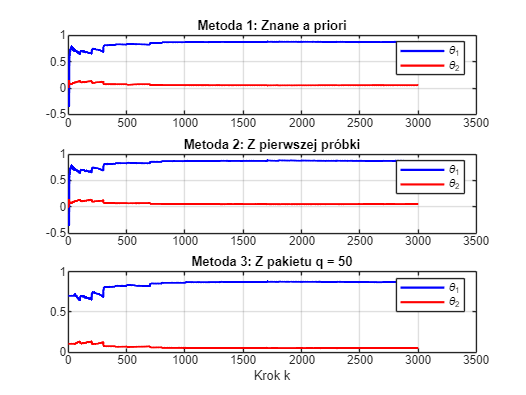

clc; clear; clear all;

load MiI_P1_grupa_1a.mat; 

y_data = y_cz1.signals.values;
u_data = u.signals.values;

% Zaszumienie
% noise_level_y = 0.02 * std(y_data); 
% noise_level_u = 0.01 * std(u_data);
% y_data = y_data + noise_level_y * randn(N, 1);
% u_data = u_data + noise_level_u * randn(N, 1);

N = length(y_data);
Waga = 1;

%% METODA 1: Znane a priori wartości początkowe
x_M1 = [0; 0]; 
P_M1 = 1000 * eye(2); % Macierz kowariancji (duża niepewność na start)

x1_M1_hist = zeros(N, 1);
x2_M1_hist = zeros(N, 1);
x1_M1_hist(1) = x_M1(1);
x2_M1_hist(1) = x_M1(2);

for k = 1 : N-1
    y_nowe = y_data(k+1);
    u_nowe = u_data(k+1);
    y_stare = y_data(k);
    
    [x_M1, P_M1] = krok_SMNK(y_nowe, u_nowe, y_stare, x_M1, P_M1, Waga);
    
    x1_M1_hist(k+1) = x_M1(1);
    x2_M1_hist(k+1) = x_M1(2);
end

%% METODA 2: Inicjalizacja z pierwszej próbki (k=1)
alfa = 1e6;
beta = [1e-6; 1e-6];

H_1 = [y_data(1), u_data(2)];
Y_1 = y_data(2);

% Wzory z instrukcji
P_M2 = inv((1/alfa)*eye(2) + H_1' * Waga * H_1);
x_M2 = P_M2 * ((1/alfa)*beta + H_1' * Waga * Y_1);

x1_M2_hist = zeros(N, 1);
x2_M2_hist = zeros(N, 1);
x1_M2_hist(1) = x_M2(1); 
x2_M2_hist(1) = x_M2(2);

for k = 2 : N-1 % Ruszamy od k=2, bo k=1 zużyliśmy na start
    y_nowe = y_data(k+1);
    u_nowe = u_data(k+1);
    y_stare = y_data(k);
    
    [x_M2, P_M2] = krok_SMNK(y_nowe, u_nowe, y_stare, x_M2, P_M2, Waga);
    
    x1_M2_hist(k+1) = x_M2(1);
    x2_M2_hist(k+1) = x_M2(2);
end

%% METODA 3: Inicjalizacja pakietem 'q' danych
q = 50; % Liczba początkowych próbek

Y_q = y_data(2:q+1);
Phi_q = [y_data(1:q), u_data(2:q+1)];
W_q = eye(q); 

P_M3 = inv(Phi_q' * W_q * Phi_q); 
x_M3 = P_M3 * Phi_q' * W_q * Y_q;

x1_M3_hist = zeros(N, 1);
x2_M3_hist = zeros(N, 1);
% Uzupełniamy historię dla pierwszych q próbek wyliczonym x_q
x1_M3_hist(1:q+1) = x_M3(1);
x2_M3_hist(1:q+1) = x_M3(2);

for k = q+1 : N-1 % Ruszamy dopiero po paczce q
    y_nowe = y_data(k+1);
    u_nowe = u_data(k+1);
    y_stare = y_data(k);
    
    [x_M3, P_M3] = krok_SMNK(y_nowe, u_nowe, y_stare, x_M3, P_M3, Waga);
    
    x1_M3_hist(k+1) = x_M3(1);
    x2_M3_hist(k+1) = x_M3(2);
end

%% Rysowanie wspólnego wykresu
figure('Name', 'Porównanie metod inicjalizacji SMNK', 'NumberTitle', 'off');

subplot(3,1,1);
plot(x1_M1_hist, 'b', 'LineWidth', 1.5); hold on;
plot(x2_M1_hist, 'r', 'LineWidth', 1.5);
title('Metoda 1: Znane a priori');
legend('\theta_1', '\theta_2'); grid on;

subplot(3,1,2);
plot(x1_M2_hist, 'b', 'LineWidth', 1.5); hold on;
plot(x2_M2_hist, 'r', 'LineWidth', 1.5);
title('Metoda 2: Z pierwszej próbki');
legend('\theta_1', '\theta_2'); grid on;

subplot(3,1,3);
plot(x1_M3_hist, 'b', 'LineWidth', 1.5); hold on;
plot(x2_M3_hist, 'r', 'LineWidth', 1.5);
title(['Metoda 3: Z pakietu q = ', num2str(q)]);
legend('\theta_1', '\theta_2'); grid on;
xlabel('Krok k');


%% FUNKCJA REKURSYWNA
function [x_est_next, P_next] = krok_SMNK(y_nowe, u_nowe, y_stare, x_k, P_k, W_k)
    % Zbudowanie wektora regresorów H
    H_nowe = [y_stare, u_nowe];
    
    % Wyliczenie wzmocnienia K
    K = P_k * H_nowe' * inv(H_nowe * P_k * H_nowe' + inv(W_k));
    
    % Aktualizacja estymaty parametrów
    x_est_next = x_k + K * (y_nowe - H_nowe * x_k);
    
    % Aktualizacja macierzy kowariancji
    P_next = (eye(2) - K * H_nowe) * P_k;
end
